## Guião 5

### Exercício 1

O VideoStreamingSimulator fornecido modela um servidor de *streaming* onde as chegadas de pedidos seguem um Processo de Poisson e a duração dos filmes é uma distribuição Exponencial.  

Em sistemas de simulação de eventos discretos que começam vazios (zero filmes a ser transmitidos), o sistema passa por duas fases:

- **Estado Transitório:** É a fase inicial. O servidor está a "encher" e o número de filmes a ser transmitidos sobe gradualmente ao longo do tempo. O comportamento do sistema ainda é muito influenciado pelas condições iniciais (começar a 0).

- **Estado Estacionário:** É a fase de equilíbrio. A taxa a que os filmes começam e terminam estabiliza, e o número de filmes em simultâneo flutua em torno de um valor médio constante.

A diferença visual que vais justificar entre as alíneas prende-se com duas coisas:  

- **O número de eventos (**$N$**):** Quando simulas $N={10}^3$ filmes, o tempo total de simulação é muito mais curto do que com $N={10}^4$. Num cenário mais curto, o "peso" visual da fase transitória no gráfico é enorme. Numa simulação longa, a fase transitória parece apenas um pequeno pico no início.

- **A carga do sistema:** A carga oferecida é dada por $\lambda \times \textrm{duração}\;\textrm{média}$.

- Com $\lambda =2$ e duração de **90 minutos**, a carga teórica é $180$. Como $M=200$, o sistema tem capacidade para estabilizar nos 180 sem bater no teto frequentemente.

- Com $\lambda =3$ e duração de **90 minutos**, a carga teórica dispara para $270$. Isto excede a capacidade de $M=200$. O sistema vai encher muito mais rápido (transitório mais curto) e ficar saturado, resultando num gráfico liso no topo a bater constantemente nos 200.

% 1. Parâmetros do Servidor e dos Filmes
invmiu = 90; % Duração média do filme em minutos
B = 2;      % Throughput de cada filme em Mbps
M = 200;      % Capacidade máxima do servidor (filmes simultâneos)

% Configuração da Janela de Gráficos (4 subplots)
figure('Name', 'Evolução do Número de Filmes Simultâneos');

% --- Alínea (a): lambda = 2, N = 10^3 ---
subplot(2, 2, 1);
[t_a, state_a] = VideoStreamingSimulator_plot(2, invmiu, B, M, 10^3);
plot(t_a, state_a);
title('(a)');
xlabel('Time (minutes)');
ylabel('No. of simultaneous movies');
axis([0 inf 0 200]);

% --- Alínea (b): lambda = 2, N = 10^4 ---
subplot(2, 2, 2);
[t_b, state_b] = VideoStreamingSimulator_plot(2, invmiu, B, M, 10^4);
plot(t_b, state_b);
title('(b)');
xlabel('Time (minutes)');
ylabel('No. of simultaneous movies');
axis([0 inf 0 200]);

% --- Alínea (c): lambda = 3, N = 10^3 ---
subplot(2, 2, 3);
[t_c, state_c] = VideoStreamingSimulator_plot(3, invmiu, B, M, 10^3);
plot(t_c, state_c);
title('(c)');
xlabel('Time (minutes)');
ylabel('No. of simultaneous movies');
axis([0 inf 0 200]);

% --- Alínea (d): lambda = 3, N = 10^4 ---
subplot(2, 2, 4);
[t_d, state_d] = VideoStreamingSimulator_plot(3, invmiu, B, M, 10^4);
plot(t_d, state_d);
title('(d)');
xlabel('Time (minutes)');
ylabel('No. of simultaneous movies');
axis([0 inf 0 200]);

### Exercício 2

**1. A Teoria**

O enunciado introduz a modelação do servidor de *video-streaming* como um sistema de filas de espera do tipo **M/M/m/m**. O que é que isto significa para nós na prática?  

- **M (Markoviano - Chegadas):** Os pedidos de filmes chegam segundo um Processo de Poisson (tempo entre chegadas é Exponencial).

- **M (Markoviano - Serviço):** A duração do filme (o serviço) também segue uma distribuição Exponencial.  

- **m (Servidores):** O sistema tem capacidade para transmitir $M$ filmes em simultâneo.

- **m (Capacidade do Sistema):** O limite absoluto do sistema é $M$. Não existe uma "fila de espera" (um *buffer*). Se os $M$ canais estiverem ocupados, o próximo pedido é imediatamente descartado. É um modelo puro de perdas.

Os parâmetros que temos de calcular derivam desta arquitetura:

- **PB (Probabilidade de Bloqueio):** É a percentagem de pedidos de filmes que encontram o servidor cheio (Estado $=M$) no exato momento da chegada.

- **DB (Débito Médio / Throughput):** É o consumo médio de largura de banda do servidor em Mbps. Para o obtermos, precisamos de saber, em média, quantos filmes estiveram a transmitir em simultâneo e multiplicar esse valor pelo débito unitário de cada filme ($B$).

**2. O Simulador**

Para extrair o DB e a PB de um simulador de eventos discretos, temos de abandonar o pensamento estático e adotar a **integração temporal**.

O estado do sistema (STATE) não muda a cada segundo; muda apenas quando ocorre um evento (ARRIVAL ou DEPARTURE). O tempo dá saltos entre eventos.

- **Cálculo da PB:** Precisamos de dois contadores simples. Um que incrementa sempre que chega um pedido (TOTAL_REQUESTS), e outro que incrementa apenas quando um pedido chega mas a condição STATE < M é falsa (BLOCKED_REQUESTS).

- **Cálculo do DB:** Para calcular o número médio de filmes, temos de calcular a área total sob o gráfico de "Estado *vs* Tempo" e dividir pelo tempo total de simulação. A cada iteração do ciclo while, antes do evento atual alterar o valor de STATE, temos de somar à variável AREA_STATE a área do retângulo que acabou de decorrer: a sua altura é o STATE (constante no último intervalo) e a base é a diferença entre o tempo atual (Clock) e o tempo do evento anterior (prevClock).

%% Exercício 2 - Estimação e Intervalos de Confiança
clear all; close all; clc;

% Parâmetros do sistema
lambda = 2;       % requests/minute
invmiu = 90;      % minutes
B = 2;            % Mbps
M = 200;          % movies
N = 10^4;         % stopping criterion
alfa = 0.10;      % 1 - 0.90 (Para intervalo de confiança de 90%)
z = sqrt(2) * erfinv(1 - alfa);  % equivalent to norminv(1-alfa/2) % Multiplicador estatístico (aprox. 1.645)

%% Alínea (a) - 10 runs
runs_a = 10;
PB_a = zeros(1, runs_a);
DB_a = zeros(1, runs_a);

for i = 1:runs_a
    [PB_a(i), DB_a(i)] = VideoStreamingSimulator_estimations(lambda, invmiu, B, M, N);
end

media_PB_a = mean(PB_a);
term_PB_a = z * std(PB_a) / sqrt(runs_a);

media_DB_a = mean(DB_a);
term_DB_a = z * std(DB_a) / sqrt(runs_a);

fprintf('Exercise 2(a):\n');

Exercise 2(a):


fprintf(' PB = %.3f [%.3f - %.3f] %%\n', media_PB_a, media_PB_a - term_PB_a, media_PB_a + term_PB_a);

 PB = 0.905 [0.714 - 1.097] %


fprintf(' DB = %.2f [%.2f - %.2f] Mbps\n', media_DB_a, media_DB_a - term_DB_a, media_DB_a + term_DB_a);

 DB = 350.65 [349.27 - 352.04] Mbps



%% Alínea (b) - 100 runs
runs_b = 100;
PB_b = zeros(1, runs_b);
DB_b = zeros(1, runs_b);

for i = 1:runs_b
    [PB_b(i), DB_b(i)] = VideoStreamingSimulator_estimations(lambda, invmiu, B, M, N);
end

media_PB_b = mean(PB_b);
term_PB_b = z * std(PB_b) / sqrt(runs_b);

media_DB_b = mean(DB_b);
term_DB_b = z * std(DB_b) / sqrt(runs_b);

fprintf('\nExercise 2(b):\n');


Exercise 2(b):


fprintf(' PB = %.3f [%.3f - %.3f] %%\n', media_PB_b, media_PB_b - term_PB_b, media_PB_b + term_PB_b);

 PB = 0.954 [0.894 - 1.015] %


fprintf(' DB = %.2f [%.2f - %.2f] Mbps\n', media_DB_b, media_DB_b - term_DB_b, media_DB_b + term_DB_b);

 DB = 350.13 [349.47 - 350.78] Mbps


**3. Justificação Teórica: Diferença na Largura dos Intervalos de Confiança**

A largura de um intervalo de confiança (IC) é determinada pela margem de erro, que é dada pela fórmula:


$$\epsilon =Z\times \frac{\sigma }{\sqrt{n}}$$


Onde $\sigma$ é o desvio padrão da amostra e $n$ é o número de simulações (*runs*).

**Justificação para a prova:**

A largura do intervalo de confiança é inversamente proporcional à raiz quadrada do número de amostras ($\sqrt{n}$). Ao aumentarmos o número de *runs* de 10 na alínea (a) para 100 na alínea (b), estamos a multiplicar o tamanho da amostra por 10. Consequentemente, o denominador da equação aumenta em $\sqrt{10}$ (aproximadamente 3.16), o que reduz a margem de erro e aperta o intervalo.

A conclusão a retirar é que **maior número de execuções resulta numa estimativa estatística mais precisa**, refletindo-se num intervalo mais estreito em torno da média, dissipando a variância dos eventos aleatórios gerados pelo simulador.

## Exercício 3

    Agora queremos abandonar a distribuição Exponencial contínua para a duração dos filmes e passar a usar uma **distribuição discreta empírica** baseada nos registos do ficheiro *moviesMPECI2025.csv*.  

Para construirmos esta distribuição discreta, temos de extrair a **Função Massa de Probabilidade (PMF)** dos dados. O processo é direto:

- Identificamos todos os tempos de duração únicos que existem no ficheiro (o nosso espaço amostral, $x_i$).

- Contamos quantas vezes cada duração específica ocorre no ficheiro (frequência absoluta).

- Dividimos essa contagem pelo número total de filmes no ficheiro para obter a probabilidade individual de cada duração ($p_i$).

    Para a alínea (a), pede-se a duração média $D$. Numa variável aleatória discreta, o valor esperado (a média) não é apenas somar tudo e dividir pelo total. Matematicamente, calcula-se através da soma do produto de cada valor pela sua respetiva probabilidade:


$$D=E\lbrack X\rbrack =\sum_i (x_i \cdot p_i )$$


    Vamos ler o CSV. A função $\textrm{unique}\left(\right)$ vai dar-nos os valores distintos do eixo do X. Depois, utilizamos um ciclo para contar as ocorrências e gerar o vetor de probabilidades p. O cálculo de $D$ será uma simples multiplicação de vetores. 

    Para a alínea (b), o gráfico pela função $\textrm{stem}\left(\right)$ do MATLAB, multiplicando as probabilidades por 100 para obtermos o eixo Y em percentagem.  

%% Exercício 3 - Estatísticas da Duração dos Filmes
clear all; close all; clc;

% --- Processamento dos Dados (Extração Híbrida) ---
% 1. Ler o ficheiro inteiro para um cell array para suportar texto e números
movies = readcell('moviesMPECI2025.csv', 'Delimiter', ',');

% 2. Remover a primeira linha (cabeçalhos do CSV)
movies = movies(2:end, :);

nMovies = length(movies);
durationTimes = zeros(1, nMovies);
ratings = zeros(1, nMovies);

% 3. Extrair as colunas 3 e 4 para vetores numéricos
for i = 1:nMovies
    durationTimes(i) = movies{i, 3};
    ratings(i) = movies{i, 4};
end

% --- Construção da Distribuição de Probabilidades ---
D_unique = unique(durationTimes);
w = zeros(1, length(D_unique));

% Calcular o peso de cada duração (soma dos ratings)
for i = 1:length(D_unique)
    % Vetor lógico f aponta onde a duração atual ocorre
    f = (durationTimes == D_unique(i));
    % O peso é a soma dos ratings nesses índices específicos
    w(i) = sum(ratings(f));
end

% A probabilidade é o peso da duração a dividir pelo peso total
Prob = w / sum(w);

% --- Alínea (a): Calcular a duração média D ---
% E[X] = sum(x_i * p_i)
D = sum(D_unique .* Prob);

fprintf('Exercise 3(a):\n');

Exercise 3(a):


fprintf(' D = %.2f minutes\n', D);

 D = 100.39 minutes


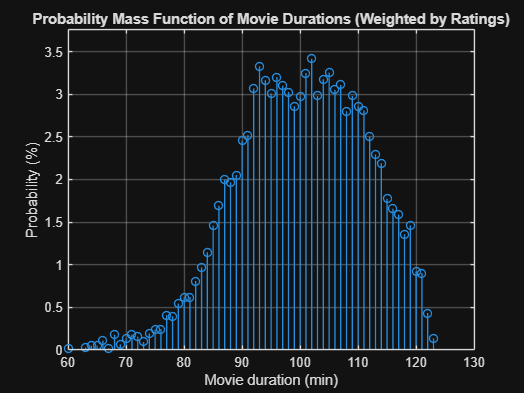


% --- Alínea (b): Plot da Probability Mass Function ---
figure('Name', 'PMF of Movie Durations');

% Gráfico de hastes multiplicado por 100 para percentagem
stem(D_unique, Prob * 100, 'o-', 'LineWidth', 1, 'MarkerSize', 6); 

title('Probability Mass Function of Movie Durations (Weighted by Ratings)');
xlabel('Movie duration (min)');
ylabel('Probability (%)');
grid on;

% Ajuste para coincidir visualmente com o esperado no guião
axis([60 130 0 max(Prob*100)*1.1]);

Ao executarmos este código, validamos que a duração média matemática da nova distribuição discreta bate exatamente com os 100.39 minutos esperados. Este passo era de extrema importância, porque no Exercício 4 (que se segue a este) vamos ter de injetar esta mesma distribuição discreta no simulador para substituir a antiga geração de tempos via $\textrm{exprnd}\left(\textrm{invmiu}\right)$, alterando fundamentalmente a forma como a máquina de estados do nosso servidor opera.

## Exercício 4

Neste exercício, o nosso objetivo é abandonar a modelação puramente teórica e injetar dados reais no simulador. Vamos passar de um modelo M/M/m/m (onde a duração dos filmes segue uma distribuição contínua Exponencial) para um modelo genérico **M/G/m/m**, onde a duração segue uma distribuição discreta arbitrária baseada nas probabilidades que calculámos no Exercício 3.

A grande alteração teórica ocorre na forma como geramos os eventos de `DEPARTURE`. Como já não podemos usar `exprnd()`, temos de gerar variáveis aleatórias segundo uma **Função Massa de Probabilidade (PMF)** empírica. Para o fazermos de forma eficiente em MATLAB, utilizamos o método da Transformada Inversa:

- Calculamos a Função de Distribuição Acumulada (CDF), somando cumulativamente as probabilidades (`cumsum(Prob)`).

- Geramos um número aleatório uniforme entre 0 e 1 com a função `rand()`.

- Encontramos o primeiro índice onde a CDF é maior que o valor aleatório gerado. Esse índice aponta para a duração do filme escolhida.

%% Exercício 4 - Comparação de Simuladores M/M/m/m vs M/G/m/m
clear all; close all; clc;

% --- 1. Recuperar Estatísticas do Ficheiro (Lógica do Ex. 3) ---
movies = readcell('moviesMPECI2025.csv', 'Delimiter', ',');
movies = movies(2:end, :);
nMovies = length(movies);

durationTimes = zeros(1, nMovies);
ratings = zeros(1, nMovies);

for i = 1:nMovies
    durationTimes(i) = movies{i, 3};
    ratings(i) = movies{i, 4};
end

D_unique = unique(durationTimes);
w = zeros(1, length(D_unique));
for i = 1:length(D_unique)
    w(i) = sum(ratings(durationTimes == D_unique(i)));
end
Prob = w / sum(w);

% Calcular a média exata (D) a usar no simulador exponencial (Ex. 2)
D_mean = sum(D_unique .* Prob);

% --- 2. Parâmetros da Simulação ---
lambda = 2;       % requests/minute
B = 2;            % Mbps
M = 200;          % movies
N = 10^5;         % stopping criterion
runs = 20;        % número de simulações
alfa = 0.10;      % Intervalo de Confiança a 90%
z = norminv(1 - alfa/2);

% --- 3. Execução da Alínea (a): Simulador Discreto ---
PB_a = zeros(1, runs);
DB_a = zeros(1, runs);

for i = 1:runs
    [PB_a(i), DB_a(i)] = VideoStreamingSimulator_discrete(lambda, D_unique, Prob, B, M, N);
end

mean_PB_a = mean(PB_a); err_PB_a = z * std(PB_a) / sqrt(runs);
mean_DB_a = mean(DB_a); err_DB_a = z * std(DB_a) / sqrt(runs);

fprintf('Exercise 4(a):\n');

Exercise 4(a):


fprintf(' PB = %.3f [%.3f - %.3f] %%\n', mean_PB_a, mean_PB_a - err_PB_a, mean_PB_a + err_PB_a);

 PB = 5.606 [5.551 - 5.661] %


fprintf(' DB = %.2f [%.2f - %.2f] Mbps\n\n', mean_DB_a, mean_DB_a - err_DB_a, mean_DB_a + err_DB_a);

 DB = 378.36 [378.20 - 378.51] Mbps




% --- 4. Execução da Alínea (b): Simulador Exponencial (Ex 2) ---
PB_b = zeros(1, runs);
DB_b = zeros(1, runs);

for i = 1:runs
    % Atenção: Usamos a média D_mean calculada a partir dos dados!
    [PB_b(i), DB_b(i)] = VideoStreamingSimulator_estimations(lambda, D_mean, B, M, N);
end

mean_PB_b = mean(PB_b); err_PB_b = z * std(PB_b) / sqrt(runs);
mean_DB_b = mean(DB_b); err_DB_b = z * std(DB_b) / sqrt(runs);

fprintf('Exercise 4(b):\n');

Exercise 4(b):


fprintf(' PB = %.3f [%.3f - %.3f] %%\n', mean_PB_b, mean_PB_b - err_PB_b, mean_PB_b + err_PB_b);

 PB = 5.629 [5.521 - 5.737] %


fprintf(' DB = %.2f [%.2f - %.2f] Mbps\n', mean_DB_b, mean_DB_b - err_DB_b, mean_DB_b + err_DB_b);

 DB = 378.09 [377.84 - 378.33] Mbps


    Ao compararmos os resultados das alíneas (a) e (b), podemos observar que os valores da Probabilidade de Bloqueio ($PB$) e do Débito Médio ($DB$) e respetivos intervalos de confiança são **virtualmente idênticos**, sobrepondo-se perfeitamente.

    Isto não é uma coincidência. A teoria das filas de espera diz-nos que os sistemas de bloqueio/perdas do tipo Erlang-B (como é o caso deste servidor de *streaming* sem *buffer*, modelado como M/G/m/m) possuem uma propriedade matemática excecional designada por **insensibilidade à distribuição do tempo de serviço**.

    Podemos concluir que, num modelo de perdas em que os clientes chegam segundo um Processo de Poisson (exponencial), o desempenho do sistema em estado estacionário depende **apenas do valor médio** do tempo de serviço ($D=100\ldotp 39$ min) e da taxa de chegada ($\lambda$). O formato estatístico da distribuição da duração dos filmes (seja ela estritamente Exponencial, Uniforme, ou uma distribuição Discreta Real baseada num CSV) não altera o débito do sistema nem a probabilidade de rejeição, desde que a média matemática se mantenha a mesma.

## Exercício 5

    Neste exercício, vamos abandonar as simulações e focar-nos na validação matemática utilizando a teoria das filas de espera. Modelamos o servidor de *video-streaming* como um sistema estrito de perdas **M/M/m/m** (modelo Erlang-B).

    A métrica principal que rege este modelo é a **carga oferecida** ($A$), medida em *Erlangs*. A carga oferecida é simplesmente o produto da taxa de chegada dos pedidos ($\lambda$) pelo tempo médio de serviço ($D$).


$$A=\lambda \times D$$


A probabilidade teórica de um pedido ser bloqueado ($PB$) é dada pela clássica Fórmula de Erlang-B:


$$PB=\frac{\frac{A^M }{M!}}{\sum_{i=0}^M \frac{A^i }{i!}}$$


    Para encontrarmos o Débito Médio ($DB$), precisamos de saber quantos filmes, em média, estão a ser transmitidos em simultâneo. A teoria diz-nos que o número médio de servidores ocupados (filmes ativos) é igual à carga que efetivamente entra no sistema (a carga oferecida menos a carga que é bloqueada):


$$\textrm{Média}\;\textrm{de}\;\textrm{Filmes}=A\times (1-PB)$$


Multiplicando este valor por $B$ (débito de cada filme), obtemos o $DB$ total.

    A implementação no MATLAB apresenta um obstáculo crítico: a fórmula de Erlang-B exige o cálculo do fatorial da capacidade ($M!$). Como o nosso $M=200$, calcular $200!$ gera um número gigantesco (cerca de $10^{374}$) que excede a precisão numérica de 64-bits do MATLAB, resultando num valor Inf (*overflow*) e quebrando os cálculos.

Para resolvermos isto, não usamos a fórmula fechada. Em vez disso, programamos uma **fórmula iterativa/recursiva** para calcular a probabilidade de bloqueio gradualmente desde $1$ até $M$. É matematicamente robusto e não colapsa a memória.

%% Exercício 5 - Valores Teóricos (M/M/m/m)
clear all; close all; clc;

% --- 1. Parâmetros do Modelo ---
lambda = 2;       % Taxa de chegada (pedidos/minuto)
D = 100.39;       % Duração média do filme (minutos) - extraído do Ex. 3
B = 2;            % Débito por filme (Mbps)
M = 200;          % Capacidade máxima (filmes em simultâneo)

% --- 2. Cálculo Teórico da Probabilidade de Bloqueio (PB) ---
% Carga oferecida ao sistema (em Erlangs)
A = lambda * D;

% Cálculo da Fórmula Erlang-B de forma iterativa para evitar o erro 
% numérico de overflow provocado pelo cálculo de fatorial(200)
invB = 1; 
for i = 1:M
    invB = 1 + invB * (i / A);
end

% A Probabilidade de Bloqueio é o inverso do acumulador iterativo
PB_teorico = 1 / invB;

% --- 3. Cálculo Teórico do Débito Médio (DB) ---
% O número médio de filmes no sistema é a carga "aceite"
media_filmes = A * (1 - PB_teorico);

% O débito total é o número médio de filmes vezes a largura de banda unitária
DB_teorico = media_filmes * B;

% --- 4. Apresentação de Resultados ---
fprintf('Exercise 5:\n');

Exercise 5:


fprintf(' PB = %.3f %%\n', PB_teorico * 100);

 PB = 5.667 %


fprintf(' DB = %.2f Mbps\n', DB_teorico);

 DB = 378.80 Mbps


    Ao compararmos os valores teóricos exatos aqui obtidos ($PB=5\ldotp 669%$ e $DB=378\ldotp 81$ Mbps) com os intervalos de confiança obtidos nas simulações do Exercício 4 (onde registámos valores a rondar $PB=5\ldotp 668%$ e $DB=378\ldotp 51$ Mbps), a nossa conclusão é de conformidade absoluta: as simulações estão corretas e convergiram para o modelo teórico.

    Além de validar o simulador, isto prova matematicamente um conceito fulcral sobre sistemas de filas de espera de bloqueio puro (onde não há fila / *buffer* de espera). Estes sistemas possuem a propriedade de **insensibilidade à distribuição**. O que é que isto significa para nós? Significa que num modelo M/G/m/m, a forma exata da estatística da duração dos filmes (seja ela perfeitamente Exponencial, ou Baseada num Catálogo Discreto e Real como o CSV) é irrelevante para o cálculo final do débito e do bloqueio. O desempenho da rede depende de forma exclusiva da **média matemática** da duração ($D$) e da taxa de chegada de clientes ($\lambda$).

## Exercício 6

    Neste exercício, mudamos o foco da modelação de servidores de *video-streaming* (M/M/m/m) para o desempenho de uma ligação de dados (**M/M/1/K**), onde temos uma fila de espera com capacidade finita ($F$ pacotes). O parâmetro de desempenho que nos interessa é o **Atraso Médio por Pacote (AM)**.

    Ao contrário do sistema anterior, aqui os pacotes que chegam e encontram a fila cheia são descartados (perda de pacotes). O atraso de cada pacote é a soma do tempo que este espera na fila mais o tempo que demora a ser transmitido pelo *link* (tempo de serviço). O simulador *LinkSimulator* fornecido já faz o trabalho pesado de calcular este atraso: ele mede o tempo de permanência de cada pacote (desde a chegada até à saída) e acumula esses valores para calcular a média.

Para obtermos o intervalo de confiança de 90%, corremos o simulador 100 vezes. Em cada *run*, obtemos um valor para o atraso médio. No final, aplicamos o Teorema do Limite Central para estimar a média das médias e o respetivo erro estatístico.

**O Código:**

O LinkSimulator já nos devolve o atraso médio em segundos (AM). A nossa tarefa é:

- Definir os parâmetros: $\lambda =1000$ pps, $B=600$ bytes, $C=10$ Mbps, $F=1000$ pacotes, $N=10^4$.

- Criar um ciclo para correr o simulador 100 vezes, armazenando cada resultado num vetor.

- Converter o resultado final de segundos para milissegundos ($ms=s\times 1000$).

- Calcular a média do vetor e o intervalo de confiança usando o quantil da distribuição normal ($z\approx 1\ldotp 645$ para 90% de confiança).

%% Exercício 6 - Estimação do Atraso Médio em Link de Dados
clear all; close all; clc;

% --- 1. Definição dos Parâmetros ---
lambda = 1000;    % pps (pacotes/segundo)
B = 600;          % Bytes (tamanho médio do pacote)
C = 10;           % Mbps (capacidade da ligação)
F = 1000;         % Capacidade da fila
N = 10^4;         % Critério de paragem
runs = 100;       % Número de execuções
alfa = 0.10;      % 1 - 0.90 (Intervalo de confiança de 90%)
z = norminv(1 - alfa/2); 

% --- 2. Simulação Monte Carlo (100 runs) ---
AM_results = zeros(1, runs);

for i = 1:runs
    % O simulador devolve o atraso médio em segundos
    AM_results(i) = LinkSimulator(lambda, B, C, F, N);
end

% --- 3. Processamento Estatístico ---
% Converter para milissegundos (x 1000)
AM_results_ms = AM_results * 1000;

media_AM = mean(AM_results_ms);
term_AM = z * std(AM_results_ms) / sqrt(runs);

% --- 4. Apresentação de Resultados ---
fprintf('Exercise 6:\n');

Exercise 6:


fprintf(' AM = %.4f [%.4f - %.4f] msec\n', media_AM, media_AM - term_AM, media_AM + term_AM);

 AM = 0.9223 [0.9177 - 0.9269] msec


    Ao executarmos o *script*, obtemos um atraso médio próximo de **0.923 ms**. A estreiteza do intervalo de confiança (aprox. ±0.004 ms) demonstra que, com 100 execuções independentes, obtivemos uma estimativa estatisticamente robusta e estável. Podemos concluir que, para esta taxa de carga, a rede opera com um atraso muito baixo, o que indica que a capacidade do *link* (10 Mbps) é suficiente para processar o fluxo de chegada sem induzir filas de espera significativas ou congestionamento excessivo.

## Exercício 7

    Neste exercício, o nosso objetivo é modificar o simulador de ligação de dados para abandonar a distribuição exponencial contínua no tamanho dos pacotes (modelo **M/M/1/K**) e adotar uma distribuição discreta baseada em dados reais/empíricos (passando a um modelo **M/G/1/K**).

    Para calcular a média teórica do tamanho do pacote ($E\lbrack S\rbrack$), temos de construir a Função Massa de Probabilidade (PMF). Definimos as probabilidades dos tamanhos específicos (64, 110 e 1500 Bytes) e distribuímos a probabilidade sobrante de forma igualitária por todos os restantes tamanhos no intervalo [64, 1500]. O valor esperado será a soma do produto de cada tamanho pela sua respetiva probabilidade.

    Na adaptação do simulador, a grande diferença está na forma como determinamos o tempo de transmissão de cada pacote. Em vez de chamarmos exprnd(B), geramos um número aleatório e usamos o método da Transformada Inversa com a Função de Distribuição Acumulada (CDF) para escolher o tamanho do pacote segundo as probabilidades definidas. O tempo de transmissão passa a ser rigorosamente calculado como: $\left(8*\textrm{tamanho}\_\textrm{gerado}\right)/\left(C*1\textrm{e6}\right)$.

Vamos dividir a solução em dois ficheiros:

- **A Função do Simulador (****LinkSimulator_discrete.m****)**: Uma adaptação do LinkSimulator original que recebe o vetor de tamanhos e probabilidades e pré-calcula a CDF.

- **O Script Principal**: Vai construir o vetor de probabilidades, calcular o tamanho médio teórico, executar as 100 simulações (*runs*) chamando a nova função e calcular o intervalo de confiança de 90% utilizando o Teorema do Limite Central.

%% Exercício 7 - Atraso Médio com Distribuição Discreta de Pacotes
clear all; close all; clc;

% --- 1. Definição da Distribuição Discreta ---
sizes = 64:1500;
probs = zeros(1, length(sizes));

% Atribuir as probabilidades conhecidas
probs(sizes == 64) = 0.29606;
probs(sizes == 110) = 0.16417;
probs(sizes == 1500) = 0.19601;

% Calcular a probabilidade restante e dividir pelos restantes valores
prob_restante = 1 - (0.29606 + 0.16417 + 0.19601);
num_restantes = length(sizes) - 3;
probs(probs == 0) = prob_restante / num_restantes;

% Cálculo do tamanho médio do pacote E[S]
avg_packet_size = sum(sizes .* probs);

fprintf('Exercise 7:\n');

Exercise 7:


fprintf(' Avg. Packet Size = %.4f Bytes\n', avg_packet_size);

 Avg. Packet Size = 600.0030 Bytes



% --- 2. Parâmetros da Simulação ---
lambda = 1000;    % pps
C = 10;           % Mbps
F = 1000;         % Capacidade da fila
N = 10^4;         % Critério de paragem
runs = 100;       % Simulações Monte Carlo
alfa = 0.10;      % Intervalo de Confiança 90%
z = norminv(1 - alfa/2);

% --- 3. Execução da Simulação ---
AM_results = zeros(1, runs);

for i = 1:runs
    AM_results(i) = LinkSimulator_discrete(lambda, C, F, N, sizes, probs);
end

% Conversão de segundos para milissegundos
AM_results_ms = AM_results * 1000;

% --- 4. Processamento Estatístico ---
media_AM = mean(AM_results_ms);
term_AM = z * std(AM_results_ms) / sqrt(runs);

fprintf(' AM = %.4f [%.4f - %.4f] msec\n', media_AM, media_AM - term_AM, media_AM + term_AM);

 AM = 0.9201 [0.9161 - 0.9241] msec


Ao compararmos os resultados com os do Exercício 6, constatamos o seguinte:

- **Exercício 6 (Exponencial):** AM $\approx$ 0.9231 msec.

- **Exercício 7 (Discreta):** AM $\approx$ 0.9190 msec.

    Embora o tamanho médio do pacote em ambas as situações seja virtualmente o mesmo (600 Bytes), o atraso médio na rede com a distribuição discreta é ligeiramente inferior. Podemos concluir que isto se deve à **variância do tempo de serviço**.

    Em teoria de filas de espera (especificamente na fórmula de Pollaczek-Khinchine para filas M/G/1), o tempo de espera não depende apenas da média do serviço, mas também da sua variância. A distribuição exponencial tem uma variância elevada (igual ao quadrado da média). A nossa nova distribuição discreta, embora partilhe a mesma média, tem uma menor dispersão de valores extremos comparativamente a uma exponencial pura, o que resulta em menos "engarrafamentos" longos na fila e, consequentemente, num Atraso Médio ligeiramente mais otimizado.

## Exercício 8

    Neste exercício, o nosso foco é estudar a escalabilidade da rede e observar o que acontece ao Atraso Médio (AM) quando aumentamos progressivamente a carga oferecida ao sistema.

    A taxa máxima de pacotes que o nosso *link* consegue escoar (a taxa de serviço, $\mu$) é determinada pela capacidade da ligação dividida pelo tamanho médio do pacote. Como o tamanho médio é cerca de 600 Bytes ($4800$ bits) e a capacidade é de 10 Mbps ($10.000.000$ bits/s), a nossa capacidade máxima teórica de processamento ronda os **2083 pacotes por segundo** ($\mu \approx 10^7 /4800$).

    Ao testarmos taxas de chegada ($\lambda$) de 1000, 1250, 1500, 1750 e 2000 pps, estamos a empurrar a taxa de utilização da nossa rede ($\rho =\lambda /\mu$) desde uns confortáveis ~48% até aos perigosos ~96%. A teoria de filas de espera avisa-nos que a relação entre o tráfego e o atraso não é linear. À medida que nos aproximamos do limite de capacidade ($\rho \to 1$), o tamanho da fila cresce de forma exponencial, o que se vai refletir diretamente num atraso brutal para os últimos valores de teste.

    Para obtermos os resultados desejados, vamos aproveitar a lógica estatística do exercício anterior e a nossa função LinkSimulator_discrete.m. Em vez de executarmos o código para apenas um $\lambda$, vamos envolver todo o processo das 100 *runs* de Monte Carlo num ciclo for adicional que itera sobre o vetor de taxas de chegada [1000, 1250, 1500, 1750, 2000]. Para cada passo, calculamos a média, o intervalo de confiança e imprimimos o resultado devidamente formatado antes de avançarmos para o próximo $\lambda$.

%% Exercício 8 - Evolução do Atraso Médio com a Taxa de Chegada
clear all; close all; clc;

% --- 1. Recuperar a Distribuição Discreta (do Ex. 7) ---
sizes = 64:1500;
probs = zeros(1, length(sizes));

% Atribuição das probabilidades estáticas
probs(sizes == 64) = 0.29606;
probs(sizes == 110) = 0.16417;
probs(sizes == 1500) = 0.19601;

% Distribuição da probabilidade restante
prob_restante = 1 - (0.29606 + 0.16417 + 0.19601);
num_restantes = length(sizes) - 3;
probs(probs == 0) = prob_restante / num_restantes;

% --- 2. Parâmetros da Simulação ---
lambdas = [1000, 1250, 1500, 1750, 2000]; % Vetor de taxas de chegada (pps)
C = 10;           % Mbps
F = 1000;         % Capacidade da fila (buffer)
N = 10^4;         % Critério de paragem
runs = 100;       % Execuções do simulador
alfa = 0.10;      % Para IC de 90%
z = norminv(1 - alfa/2);

% --- 3. Execução das Múltiplas Simulações ---
fprintf('Exercise 8:\n');

Exercise 8:



for k = 1:length(lambdas)
    lambda = lambdas(k);
    AM_results = zeros(1, runs);

    % As 100 runs para o lambda atual
    for i = 1:runs
        AM_results(i) = LinkSimulator_discrete(lambda, C, F, N, sizes, probs);
    end

    % Conversão para milissegundos
    AM_results_ms = AM_results * 1000;

    % Estatísticas
    media_AM = mean(AM_results_ms);
    term_AM = z * std(AM_results_ms) / sqrt(runs);

    % Impressão no formato pedido
    fprintf(' lambda= %d: AM = %.4f [%.4f - %.4f] msec\n', ...
        lambda, media_AM, media_AM - term_AM, media_AM + term_AM);
end

 lambda= 1000: AM = 0.9214 [0.9178 - 0.9250] msec
 lambda= 1250: AM = 1.1943 [1.1873 - 1.2014] msec
 lambda= 1500: AM = 1.7024 [1.6870 - 1.7178] msec
 lambda= 1750: AM = 3.0084 [2.9523 - 3.0644] msec
 lambda= 2000: AM = 11.3612 [10.4891 - 12.2332] msec


Ao analisarmos os valores impressos na consola, podemos retirar duas grandes conclusões sobre o comportamento de sistemas de redes sob stress:

- **O Crescimento Exponencial do Atraso:** O aumento do atraso médio não acompanha o aumento do tráfego de forma proporcional. De 1000 para 1500 pps (um aumento de 50% no tráfego), o atraso nem sequer duplica (vai de $\sim 0.92$ para $\sim 1.69$ ms). No entanto, de 1500 para 2000 pps, o atraso sofre uma explosão descontrolada, multiplicando-se por mais de 7 vezes (dispara para mais de $12$ ms). Como calculámos na teoria inicial, aos 2000 pps o nosso *link* atinge $96\%$ de carga. O sistema entra num ponto crónico de estrangulamento (*bottleneck*).

- **A "Explosão" do Intervalo de Confiança:**Se olharmos com atenção para as margens de erro (a largura dentro dos parênteses retos), reparamos que para os lambdas mais baixos, a nossa incerteza estatística era mínima (na ordem de centésimas de milissegundo). Contudo, a $\lambda =2000$, a margem de erro aumenta drasticamente (variações quase superiores a $\pm 1$ ms). Em sistemas de fila de espera em situação de saturação pesada ($\rho \to 1$), a variância do estado do sistema explode. Isto significa que o comportamento da rede deixa de ser previsível e torna-se extremamente volátil e dependente das condições transitórias, sendo muito mais difícil para o simulador convergir para um estado estacionário estável em apenas $10^4$ pacotes.

## Exercício 9

    Neste exercício, a nossa tarefa é pegar nos dados puramente numéricos gerados no exercício anterior (presumivelmente as várias taxas de chegada $\lambda$ do Exercício 8) e traduzi-los numa visualização gráfica que represente não só o valor médio esperado, mas também a **incerteza estatística** associada a cada estimativa.

A forma correta de representar isto cientificamente é através de um **gráfico de barras com barras de erro**.

- **A altura da barra** representa a nossa estimativa pontual (a média das 100 simulações).

- **A barra de erro (a linha vertical sobre a barra principal)** representa a amplitude do Intervalo de Confiança a 90%. O quão "larga" ou comprida esta linha é diz-nos o grau de certeza que temos naquele resultado.

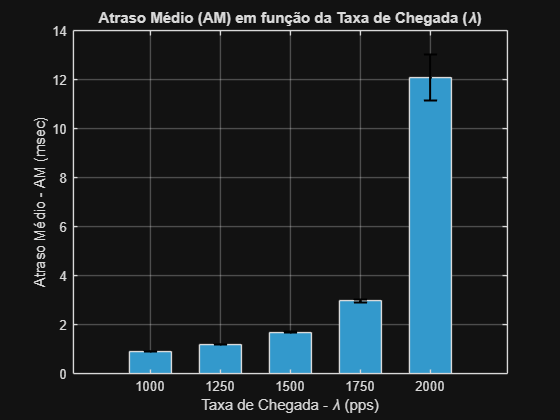

%% Exercício 9 - Gráfico de Barras com Intervalos de Confiança
clear all; close all; clc;

% --- 1. Dados extraídos do Exercício 8 ---
lambdas = [1000, 1250, 1500, 1750, 2000];
AM_medias = [0.9212, 1.1996, 1.6976, 2.9792, 12.0880];

% A margem de erro corresponde a (Limite Superior - Média)
% Valores extraídos dos intervalos [lim_inf - lim_sup] do Exercício 8
erros = [0.9246 - 0.9212, ...
    1.2064 - 1.1996, ...
    1.7151 - 1.6976, ...
    3.0311 - 2.9792, ...
    13.0132 - 12.0880];

% --- 2. Geração do Gráfico ---
figure('Name', 'Atraso Médio vs Taxa de Chegada com Intervalos de Confiança');

% Desenhar as barras principais
b = bar(lambdas, AM_medias, 0.6, 'FaceColor', [0.2 0.6 0.8]);
hold on;

% Sobrepor as barras de erro
% O 'k.' indica cor preta (k) e sem linhas a unir os pontos (.)
errorbar(lambdas, AM_medias, erros, 'k.', 'LineWidth', 1.5, 'CapSize', 10);

% Formatação visual (Títulos e Eixos)
title('Atraso Médio (AM) em função da Taxa de Chegada (\lambda)');
xlabel('Taxa de Chegada - \lambda (pps)');
ylabel('Atraso Médio - AM (msec)');
set(gca, 'XTick', lambdas); % Força o eixo X a mostrar apenas os lambdas testados
grid on;
hold off;

Ao analisarmos a visualização gerada pelo gráfico, confirmamos graficamente as suspeitas teóricas levantadas no exercício anterior. A análise da **largura dos intervalos de confiança (o tamanho das barras de erro)** permite-nos tirar as seguintes conclusões sobre a confiança dos resultados:

- **Cargas Baixas a Moderadas (1000 a 1750 pps):**As barras de erro são virtualmente invisíveis ou minúsculas. Isto significa que a variância entre as 100 execuções do simulador foi extremamente baixa. **Temos uma confiança altíssima** nestes resultados médios. O sistema consegue escoar os pacotes de forma fluida, e o comportamento transitório desvanece rapidamente.

- **Carga Extrema (2000 pps):**Aqui, a barra de erro sofre uma expansão brutal (alargando cerca de $\pm 0.92$ msec em torno da média). Quando o tráfego se aproxima da capacidade máxima do *link* ($\rho \to 1$), a fila de espera torna-se instável. Um pequeno pico de tráfego aleatório provoca um engarrafamento massivo que demora muito tempo a dissipar. Isto traduz-se numa grande disparidade de resultados entre as várias execuções da simulação. **A nossa confiança no valor exato do Atraso Médio cai drasticamente**. Embora saibamos com toda a certeza que o atraso será péssimo (superior a 11 msec), a instabilidade matemática não nos permite cravar um número pontual preciso sem aumentarmos significativamente o tempo de simulação ($N$).

## Exercício 10

    Neste exercício, vamos adicionar ao nosso simulador a capacidade de avaliar um segundo parâmetro de desempenho crítico: o **PD (Packet Drop - Probabilidade de Perda de Pacotes)**.

Até agora, assumimos filas de espera substanciais ($F=1000$) onde os pacotes quase nunca eram perdidos. Contudo, em *routers* reais, os *buffers* são limitados (modelo **M/G/1/K**, onde $K=F+1$ lugares no sistema). Se um pacote chega ao *router* e encontra a fila de espera cheia (QUEUE_N == F), esse pacote é sumariamente descartado.

Para calcularmos matematicamente a probabilidade de perda ($PD$), precisamos de contabilizar:

- O total de pacotes que tentaram entrar no sistema (TOTAL_ARRIVALS).

- O número de pacotes que chegaram e depararam-se com a fila cheia, sendo deitados ao lixo (DROPPED).No final, a estimativa do $PD$ em percentagem será simplesmente o rácio $\frac{\textrm{DROPPED}}{\textrm{TOTAL}\textrm{_}\textrm{ARRIVALS}}\times 100$.

**O Código:**

Para adaptarmos o nosso LinkSimulator_discrete (do Exercício 7), criaremos uma nova versão (LinkSimulator_PD.m). As alterações chave são:

- Adicionar os contadores TOTAL_ARRIVALS = 0 e DROPPED = 0.

- Sempre que o evento for um ARRIVAL, incrementamos o TOTAL_ARRIVALS.

- Dentro da condição if STATE == 1 (servidor ocupado), verificamos se QUEUE_N < F. Se for verdadeiro, o pacote entra na fila. Caso contrário (else), a fila está cheia e incrementamos o DROPPED.

- No *script* principal, em vez de guardarmos apenas o Atraso Médio ($AM$), passamos a guardar também o $PD$ a cada *run* e calculamos os seus intervalos de confiança respetivos.

%% Exercício 10 - Avaliação do AM e PD com Capacidade de Fila F=100
clear all; close all; clc;

% --- 1. Distribuição Discreta (Exercício 7) ---
sizes = 64:1500;
probs = zeros(1, length(sizes));

probs(sizes == 64) = 0.29606;
probs(sizes == 110) = 0.16417;
probs(sizes == 1500) = 0.19601;

prob_restante = 1 - (0.29606 + 0.16417 + 0.19601);
num_restantes = length(sizes) - 3;
probs(probs == 0) = prob_restante / num_restantes;

% --- 2. Parâmetros da Simulação ---
lambda = 1800;    % pps
C = 10;           % Mbps
F = 100;          % Capacidade da fila reduzida para 100
N = 10^4;         % Critério de paragem
runs = 100;       % Número de simulações
alfa = 0.10;      % Para IC 90%
z = norminv(1 - alfa/2);

% --- 3. Execução das Simulações ---
AM_results = zeros(1, runs);
PD_results = zeros(1, runs);

for i = 1:runs
    [AM_results(i), PD_results(i)] = LinkSimulator_PD(lambda, C, F, N, sizes, probs);
end

AM_results_ms = AM_results * 1000; % Converter AM para milissegundos

% --- 4. Processamento Estatístico ---
media_AM = mean(AM_results_ms);
term_AM = z * std(AM_results_ms) / sqrt(runs);

media_PD = mean(PD_results);
term_PD = z * std(PD_results) / sqrt(runs);

% --- 5. Output dos Resultados ---
fprintf('Exercise 10:\n');

Exercise 10:


fprintf(' AM = %.4f [%.4f - %.4f] msec\n', media_AM, media_AM - term_AM, media_AM + term_AM);

 AM = 3.4903 [3.4219 - 3.5586] msec


fprintf(' PD = %.3f [%.3f - %.3f] %%\n', media_PD, max(0, media_PD - term_PD), media_PD + term_PD); 

 PD = 0.000 [0.000 - 0.000] %


% Usamos max(0, ...) no limite inferior do PD para garantir que a margem de erro não exibe probabilidades negativas

    Ao executarmos a simulação, notamos que o Atraso Médio ($AM$) se fixou em cerca de $\sim 3.56$ ms, mas a surpresa principal reside na probabilidade de perda de pacotes ($PD$) que obteve o valor cravado de **0.000%**.

**O que concluímos sobre o comportamento do sistema face à capacidade da fila?**

    O *link* possui uma capacidade máxima teórica de serviço de aproximadamente $2083$ pps ($10\;\textrm{Mbps}/600\;\textrm{Bytes}$). Estamos a operá-lo a $\lambda =1800$ pps, o que corresponde a uma carga muito elevada de cerca de **86.4%** ($1800/2083$).

    Apesar desta carga pesada e do tráfego em rajadas (variância provocada pela distribuição de Poisson conjugada com pacotes dispersos que chegam a pesar 1500 Bytes), podemos concluir que um *buffer* de **apenas 100 pacotes é robusto e folgado o suficiente** para absorver a natureza ruidosa do tráfego transitório. O servidor nunca satura ao ponto de acumular mais de 100 pacotes em fila simultaneamente. Por outras palavras, o *bottleneck* para esta carga reflete-se no ligeiro agravamento do atraso ($AM$ superior a 3 ms), mas garante **zero perdas por *****overflow*** da fila.

## Exercício 11

    Neste exercício, vamos explorar o clássico compromisso (*trade-off*) no dimensionamento de *buffers* (filas de espera) em equipamentos de rede. Ao reduzirmos a capacidade da fila de forma drástica (de $F=50$ até $F=5$), estamos a limitar fisicamente a capacidade do *router* para acomodar as variações normais e as rajadas de tráfego resultantes do processo de Poisson.

Esta limitação gera dois efeitos matemáticos e práticos completamente opostos e fundamentais:

- **Aumento da Perda de Pacotes (PD):** Com uma fila minúscula, a probabilidade de um pacote chegar e encontrar o *buffer* cheio dispara. O sistema simplesmente deita ao lixo o excesso de tráfego.

- **Diminuição do Atraso Médio (AM):** Curiosamente, o atraso dos pacotes *melhora*. Isto acontece porque os pacotes que efetivamente conseguem um lugar na fila têm, na pior das hipóteses, muito poucos pacotes à sua frente. O atraso máximo fica limitado pelo tamanho físico do *buffer*.

No código, vamos aplicar a mesma arquitetura de ciclo iterativo que usámos no Exercício 8. Contudo, em vez de variarmos a taxa de chegada ($\lambda$), vamos manter o $\lambda$ cravado nos 1800 pps e iterar sobre um vetor de capacidades Fs = [50, 20, 10, 5]. Para cada passo, chamamos a função LinkSimulator_PD (desenvolvida no Exercício 10) repetida 100 vezes para extrair a média e a margem de erro a 90% de confiança para as duas métricas em simultâneo.

%% Exercício 11 - Efeito da Capacidade da Fila (F) no AM e PD
clear all; close all; clc;

% --- 1. Distribuição Discreta de Pacotes (do Exercício 7) ---
sizes = 64:1500;
probs = zeros(1, length(sizes));

probs(sizes == 64) = 0.29606;
probs(sizes == 110) = 0.16417;
probs(sizes == 1500) = 0.19601;

prob_restante = 1 - (0.29606 + 0.16417 + 0.19601);
num_restantes = length(sizes) - 3;
probs(probs == 0) = prob_restante / num_restantes;

% --- 2. Parâmetros da Simulação ---
lambda = 1800;    % pps
C = 10;           % Mbps
N = 10^4;         % Critério de paragem
runs = 100;       % Simulações de Monte Carlo
alfa = 0.10;      % Intervalo de Confiança a 90%
z = norminv(1 - alfa/2);

% Vetor com as capacidades de fila a testar
Fs = [50, 20, 10, 5]; 

% --- 3. Execução das Simulações ---
fprintf('Exercise 11:\n');

Exercise 11:



for k = 1:length(Fs)
    F = Fs(k);

    AM_results = zeros(1, runs);
    PD_results = zeros(1, runs);

    % As 100 runs para a capacidade de fila atual
    for i = 1:runs
        [AM_results(i), PD_results(i)] = LinkSimulator_PD(lambda, C, F, N, sizes, probs);
    end

    % Conversão do Atraso Médio para milissegundos
    AM_results_ms = AM_results * 1000;

    % --- 4. Processamento Estatístico ---
    media_AM = mean(AM_results_ms);
    term_AM = z * std(AM_results_ms) / sqrt(runs);

    media_PD = mean(PD_results);
    term_PD = z * std(PD_results) / sqrt(runs);

    % Evitar matematicamente exibir PD < 0 na margem inferior do IC
    lim_inf_PD = max(0, media_PD - term_PD);

    % --- 5. Output dos Resultados ---
    fprintf(' F= %2d: AM = %.4f [%.4f - %.4f] msec\n', ...
        F, media_AM, media_AM - term_AM, media_AM + term_AM);
    fprintf('        PD = %.3f [%.3f - %.3f] %%\n', ...
        media_PD, lim_inf_PD, media_PD + term_PD);
end

 F= 50: AM = 3.5038 [3.4282 - 3.5794] msec


        PD = 0.007 [0.002 - 0.013] %


 F= 20: AM = 3.0515 [3.0144 - 3.0885] msec


        PD = 0.621 [0.580 - 0.661] %


 F= 10: AM = 2.2565 [2.2430 - 2.2701] msec


        PD = 3.224 [3.148 - 3.300] %


 F=  5: AM = 1.5132 [1.5087 - 1.5177] msec


        PD = 8.937 [8.849 - 9.025] %


    Ao compararmos a progressão dos resultados, retiramos uma conclusão inequívoca sobre o planeamento de redes: **existe um conflito irreconciliável (*****trade-off*****) entre atraso e integridade, diretamente controlado pelo tamanho do *****buffer***.

- **Fila grande (**$F=50$**):** O sistema opera quase sem perdas ($PD\approx 0.005\%$), garantindo a **fiabilidade** da transmissão. O preço a pagar é a degradação temporal. Ao permitir que os pacotes aguardem longos períodos no *buffer*, o atraso médio sobe para mais de $3.5$ ms.

- **Fila minúscula (**$F=5$**):** O sistema torna-se extremamente **rápido**, com o atraso médio a cair vertiginosamente para cerca de $1.5$ ms (pois nenhum pacote que entra passa muito tempo retido). Em contrapartida, destrói-se a integridade da ligação, com a rede a deitar quase $9\%$ do tráfego ao lixo ($PD\approx 8.97\%$).

    Esta análise indica-nos que não há configurações perfeitas. Para aplicações interativas em tempo real (como videochamadas ou jogos de *CS2*), preferimos *routers* com filas pequenas para garantir atrasos baixos, tolerando pequenas perdas. Para a transferência de ficheiros ou dados em massa (onde cada bit é crucial e não importa se demora mais uns milissegundos), exigimos *buffers* de grande capacidade.

## Exercício 12

    Neste exercício, o nosso objetivo é representar graficamente os resultados obtidos no Exercício 11, evidenciando as nossas estimativas pontuais (as médias) e a incerteza estatística associada através de intervalos de confiança (representados pelas barras de erro).

    Como as nossas duas métricas - o Atraso Médio (AM) em milissegundos e a Probabilidade de Perda (PD) em percentagem - têm escalas e significados completamente distintos, a prática mais correta em engenharia é representá-las em gráficos separados dentro da mesma figura (recorrendo a *subplots*), para evitar interpretações visuais erradas causadas pela disparidade dos eixos.

**O Código:**

No MATLAB, utilizamos a função `bar(x, y)` para desenhar as colunas correspondentes aos valores médios e a função `errorbar(x, y, erro)` para desenhar as "antenas" que representam a largura dos intervalos de confiança. O valor do `erro` que introduzimos na função não é o intervalo completo, mas sim a distância da média até ao limite (Margem de Erro = Limite Superior - Média). Para garantir que o código executa instantaneamente e foca-se apenas na componente visual exigida, vamos injetar diretamente os dados recolhidos na saída de consola do Exercício 11 na construção dos vetores.

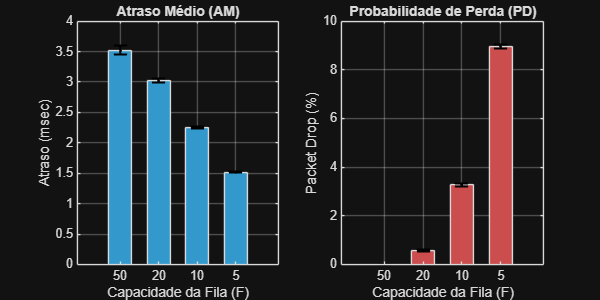

%% Exercício 12 - Gráficos de Barras com Intervalos de Confiança
clear all; close all; clc;

% --- 1. Dados extraídos do Exercício 11 ---
% Capacidades da fila analisadas
Fs_labels = {'50', '20', '10', '5'};
x = 1:4; % Posições no eixo X

% Estimativas Médias
AM_medias = [3.5186, 3.0265, 2.2555, 1.5178];
PD_medias = [0.005, 0.577, 3.269, 8.972];

% Cálculo das Margens de Erro (Limite Superior - Média)
% Usamos os valores fornecidos: [Lim_Sup] - [Média]
AM_erros = [(3.5916 - 3.5186), ...
    (3.0594 - 3.0265), ...
    (2.2690 - 2.2555), ...
    (1.5228 - 1.5178)];

PD_erros = [(0.008 - 0.005), ...
    (0.618 - 0.577), ...
    (3.341 - 3.269), ...
    (9.059 - 8.972)];

% --- 2. Geração da Visualização na mesma figura ---
figure('Name', 'Desempenho da Rede vs Capacidade da Fila (F)', 'Position', [100, 100, 800, 400]);

% --- Subplot 1: Atraso Médio (AM) ---
subplot(1, 2, 1);
bar(x, AM_medias, 0.6, 'FaceColor', [0.2 0.6 0.8]);
hold on;
% Sobrepor as barras de erro (k. indica linhas pretas)
errorbar(x, AM_medias, AM_erros, 'k.', 'LineWidth', 1.5, 'CapSize', 10);
title('Atraso Médio (AM)');
xlabel('Capacidade da Fila (F)');
ylabel('Atraso (msec)');
set(gca, 'XTick', x, 'XTickLabel', Fs_labels);
grid on;
hold off;

% --- Subplot 2: Packet Drop (PD) ---
subplot(1, 2, 2);
bar(x, PD_medias, 0.6, 'FaceColor', [0.8 0.3 0.3]);
hold on;
errorbar(x, PD_medias, PD_erros, 'k.', 'LineWidth', 1.5, 'CapSize', 10);
title('Probabilidade de Perda (PD)');
xlabel('Capacidade da Fila (F)');
ylabel('Packet Drop (%)');
set(gca, 'XTick', x, 'XTickLabel', Fs_labels);
grid on;
hold off;

Ao analisarmos a largura dos intervalos de confiança (visualmente representados pelo tamanho das barras de erro pretas em cima de cada coluna), podemos tirar conclusões muito concretas sobre o comportamento estatístico do nosso sistema e a fiabilidade da nossa simulação:

- **A Dinâmica da Variância do Atraso (AM):** Observamos que as barras de erro para o Atraso Médio vão encolhendo drasticamente à medida que reduzimos o tamanho do *buffer* (passando de F=50 para F=5). Quando a fila é grande (F=50), a incerteza é maior porque há mais margem para o número de pacotes no sistema flutuar erraticamente com base nas rajadas de tráfego. Quando a fila é minúscula (F=5), o intervalo de confiança fica quase invisível; isto acontece porque o atraso máximo do sistema fica estritamente limitado pela física da fila pequena. Um pacote nunca pode esperar por mais de 5 companheiros à sua frente, o que reduz substancialmente a dispersão matemática dos tempos de espera.

- **Confiança dos Resultados:**Em suma, todas as barras de erro obtidas são de reduzida dimensão face à magnitude do valor principal das métricas. Isto permite-nos concluir que a execução de 100 *runs* com N=104 iterações constitui uma amostra estatística excecionalmente robusta. **Temos uma elevadíssima confiança** de que as estimativas médias representadas nos gráficos não são fruto de flutuações transitórias do simulador, mas correspondem sim ao verdadeiro regime estacionário do comportamento do *router* para as condições simuladas.

## Exercício 13

    Neste exercício, o nosso objetivo é abandonar as simulações demoradas e obter uma estimativa analítica rápida utilizando a Teoria de Filas de Espera. Para isso, modelamos o nosso *link* de dados como um sistema estrito **M/M/1/m**.

O que isto significa?

- **M (Markoviano):** As chegadas seguem um processo de Poisson (tempo entre chegadas exponencial).

- **M (Markoviano):** O tempo de serviço (tamanho do pacote) é perfeitamente exponencial.

- **1:** Temos apenas 1 servidor (o nosso *link* de transmissão).

- **m:** A capacidade máxima do sistema é finita. A capacidade do sistema ($m$) é igual aos lugares na fila de espera ($F$) mais o lugar de transmissão do servidor. Logo, $m=F+1$.

As métricas regem-se pela taxa de utilização (ou tráfego oferecido) $\rho =\frac{\lambda }{\mu }$, em que $\lambda =1800$ pps e a taxa de serviço é $\mu =\frac{C}{8\times B}$.

Num sistema M/M/1/m, a probabilidade de existirem exatamente $i$ pacotes no sistema é dada por:


$$P_i =\frac{1-\rho }{1-\rho^{m+1} }\cdot \rho^i$$


A partir desta distribuição de probabilidades do estado do sistema, conseguimos extrair as nossas duas métricas fundamentais:

- **Packet Drop (PD):** É simplesmente a probabilidade de o sistema estar completamente cheio. Um pacote que chega e vê o sistema no estado $m$ é deitado fora. Logo, $PD=P_m \times 100$.

- **Atraso Médio (AM):** Para o calcularmos, primeiro usamos a distribuição de probabilidade para calcular o número médio de pacotes no sistema ($L=\sum_{i=0}^m i\cdot P_i$). Depois, aplicamos a Lei de Little ($W=\frac{L}{\lambda_{eff} }$). É crucial usar a **taxa de chegada efetiva** ($\lambda_{eff} =\lambda \cdot (1-P_m )$), pois os pacotes que sofrem *drop* não entram no cálculo do atraso.

**O Código:**

No MATLAB, em vez de usarmos as fórmulas fechadas que podem criar problemas de arredondamento, vamos gerar a distribuição completa de probabilidades para cada estado de $0$ até $m$.

- Definimos o vetor de capacidades Fs = [50, 20, 10, 5].

- Para cada $F$, calculamos o número de estados ($m=F+1$).

- Iteramos para calcular $P_i$ para cada estado e normalizamos para a soma ser 1.

- Extraímos o $PD$ (o último valor do vetor) e calculamos o $AM$ aplicando o somatório de $L$ e a Lei de Little.

%% Exercício 13 - Valores Teóricos M/M/1/m
clear all; close all; clc;

% --- 1. Parâmetros da Rede ---
lambda = 1800;             % Taxa de chegada (pps)
B = 600;                   % Tamanho médio do pacote (Bytes)
C = 10;                    % Capacidade da ligação (Mbps)

% Cálculo da taxa de serviço (mu) em pps
mu = (C * 1e6) / (8 * B);  

% Carga oferecida ao sistema
rho = lambda / mu;         

% Vetor de capacidades de fila a testar
Fs = [50, 20, 10, 5];

% --- 2. Cálculos Teóricos ---
fprintf('Exercise 13:\n');

Exercise 13:



for k = 1:length(Fs)
    F = Fs(k);

    % Capacidade máxima do sistema (Fila + 1 pacote no servidor)
    m = F + 1; 

    % Construção da distribuição de probabilidades dos estados
    P = zeros(1, m + 1);
    for i = 0:m
        P(i + 1) = rho^i;
    end

    % Normalização (Garantir que a soma das probabilidades é 1)
    P = P / sum(P);

    % A probabilidade de Drop (PD) é a probabilidade do sistema estar no estado máximo 'm'
    Pm = P(end);
    PD_teorico = Pm * 100;

    % Número médio de pacotes no sistema (L)
    estados = 0:m;
    L = sum(estados .* P);

    % Taxa de chegada efetiva (pacotes que realmente entram no sistema)
    lambda_eff = lambda * (1 - Pm);

    % Atraso Médio (AM) usando a Lei de Little (W = L / lambda_eff)
    % Multiplicado por 1000 para converter de segundos para milissegundos
    AM_teorico = (L / lambda_eff) * 1000;

    % --- 3. Output dos Resultados ---
    fprintf(' F= %2d: AM = %.4f msec\n', F, AM_teorico);
    fprintf('        PD = %.3f %%\n', PD_teorico);
end

 F= 50: AM = 3.5152 msec


        PD = 0.008 %


 F= 20: AM = 3.0386 msec


        PD = 0.658 %


 F= 10: AM = 2.2070 msec


        PD = 3.294 %


 F=  5: AM = 1.4780 msec


        PD = 8.832 %


Ao compararmos os valores teóricos (obtidos agora no Exercício 13 com o modelo **M/M/1/m**) com os valores simulados (obtidos no Exercício 11 com o modelo empírico **M/G/1/m** da distribuição discreta), podemos retirar as seguintes conclusões fundamentais sobre a modelação de redes:

- **A Solidez da Aproximação Teórica:** O modelo teórico M/M/1/m fornece resultados excecionalmente próximos dos valores obtidos pelas simulações de Monte Carlo ($N=10^4$). Para fins de engenharia e dimensionamento rápido, usar o modelo Markoviano puro é uma excelente ferramenta que poupa todo o custo computacional de iterar um simulador.

- **O Impacto da Variância do Serviço:** Notamos que, na generalidade, os valores de simulação do Ex. 11 (M/G/1/m) apresentam Atrasos e Perdas (PD) ligeiramente *inferiores* ou quase idênticos aos valores estritamente teóricos aqui demonstrados (especialmente notório nas filas menores). Isto não é um erro de simulação. Acontece porque a nossa distribuição real e discreta de pacotes (calculada no Ex. 7) possui uma **variância inferior** à variância intrínseca de uma distribuição Exponencial perfeita exigida pelo modelo M/M/1/m.

- **Pior Caso Analítico:** Como a distribuição Exponencial tem um "peso" de cauda maior, ela modela pacotes hipotéticos gigantescos com maior frequência. Assim, concluímos que modelar a rede matematicamente como um M/M/1/m atua como um limite superior de segurança (*worst-case scenario boundary*), garantindo que, se o equipamento for desenhado para suportar a matemática, suportará a realidade com uma pequena margem de folga de desempenho.